T = 8e-3; % 8 ms

Testando a saida

% Leitura da tabela
OutTab = readtable("Saidas-750.csv")

OutTab = 384×4 table
      Tempo       Entrada    Erro    Saida
    __________    _______    ____    _____

           548      41.5     750       1  
          8228     50.45     749       2  
         15804      59.4     748       2  
         23428     68.38     748       3  
         31060     77.32     747       4  
         38692     86.24     746       5  
         46332     95.14     745       6  
         53964    104.04     744       8  
         61652    112.87     742      10  
         69388    121.67     740      11  
         77132    130.51     739      10  
         84868    139.44     740      11  
         92612    148.28     739      12  
    1.0035e+05     157.1     738      12  
    1.0814e+05    165.97     738      12  
    1.1593e+05    174.84     738      12  


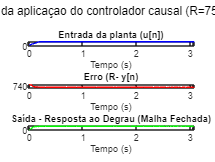


% Vetor de tempo
tout = 1:length(OutTab.Tempo);
tout = tout * T;

% Criação da figura com subplots
figure;

% Subplot 1 - Entrada
subplot(3,1,1);
plot(tout, OutTab.Entrada, 'b');
title('Entrada da planta (u[n])');
xlabel('Tempo (s)');
ylabel('Amplitude');

% Subplot 2 - Erro
subplot(3,1,2);
plot(tout, OutTab.Erro, 'r');
title('Erro (R- y[n)');
xlabel('Tempo (s)');
ylabel('Erro');

% Subplot 3 - Saída
subplot(3,1,3);
plot(tout, OutTab.Saida, 'g');
title('Saída - Resposta ao Degrau (Malha Fechada)');
xlabel('Tempo (s)');
ylabel('Resposta');


% Ajusta o layout
sgtitle('Resultados da aplicaçao do controlador causal (R=750, T = 8ms)');
hold off;

info = stepinfo(OutTab.Saida, tout);

% Tempo de acomodação a 2%
Ts = info.SettlingTime

Ts = 3.0619

Tr = info.RiseTime

Tr = 0.0912

Tp= info.PeakTime

Tp = 0.3040

UP= info.Overshoot

UP = 7.6923